## Setup

Clone repo with useful plotting function and add to search path.

!git clone https://github.com/catalystneuro/distributed-coding-matnwb.git
cd ../distributed-coding-matnwb
addpath(genpath(pwd));
cd ..

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% fetch information about units
unit_info = getUnitInfo(nwb_file);
% display number units
nunits = length(unit_info.valid_units);
fprintf('Total units: %d\n', nunits)

Total units: 606


% select unit
unit = 381;
% get and display unit info
unit_area = unit_info.area_valid(unit);
unit_depth = unit_info.depth_valid(unit);
unit_probe = unit_info.probe_valid(unit);

fprintf('Unit recorded from %s\nRecorded with probe %i at depth %.02f \x00b5m \n', unit_area{:}, unit_probe, unit_depth)

Unit recorded from VISam
Recorded with probe 1 at depth 3234.41 µm 


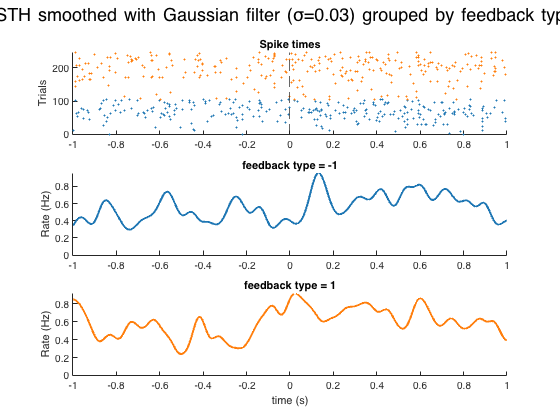

psth(...
   nwb_file, ...
   unit_id = unit_info.valid_units(unit), ...
   group_by = 'feedback_type', ...
   before_time = -1, ...
   after_time = 1, ...
   n_bins = 50, ...
   psth_plot_option = 'gaussian', ...
   std = 0.03);